Calculates theoretical threshold electric field magnitude to inactivate virus in accordance with equation 12 in Yang 2015

%Define values for variables

%Pstress in MPa

Pstress = 0.141E6;

%Total amount of charge distributed in core and shell (q) in e
q = 1.16E7;

%Reduced mass of core and shell (m*) in MDa
m_r = 14.5E6;

%Quality factor of resonator Q 
Q = 1.95;

%angular frequency of vibrational mode
w0 = 2*pi*8.72;

% radius of virion from Neuman 2006
% diameter 50-150 nm
% 100-130 nm in https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3328989/
r = 50;
r_min = 50;
r_max = 65;
% init. vector of angular freq.
f = [0:0.1:12];

%Et = TEFM(Pstress, q, m_r, Q, w0, r, f)
figure;
%plot(f, Et, 'r-');

xlabel('GHz');
ylabel('Magnitude of electric field (V/m)');

Et_min_rad = TEFM(Pstress, q, m_r, Q, w0, r_min, f);

Et =   173.8648
  173.8450
  173.7854
  173.6861
  173.5472
  173.3686
  173.1504
  172.8927
  172.5954
  172.2587


hold on;
plot(f, Et_min_rad, 'g-');
Et_max_rad = TEFM(Pstress, q, m_r*(65/50), Q, w0, r_max, f);

Et =   293.8316
  293.7980
  293.6974
  293.5296
  293.2948
  292.9929
  292.6242
  292.1886
  291.6862
  291.1173


hold on;
plot(f, Et_max_rad, 'b-');

[~,I] = min(Et)

I = 82


min_TEMF = TEFM(Pstress, q, m_r, Q, w0, r, f(1+I));

Et = 86.2243

hold on;
plot(f(1+I), min_TEMF, 'ro', 'MarkerSize', 10);

[~,I] = min(Et_max_rad)

I = 82


min_TEMF_max = TEFM(Pstress, q, m_r*(65/50), Q, w0, r_max, f(1+I));

Et = 145.7191

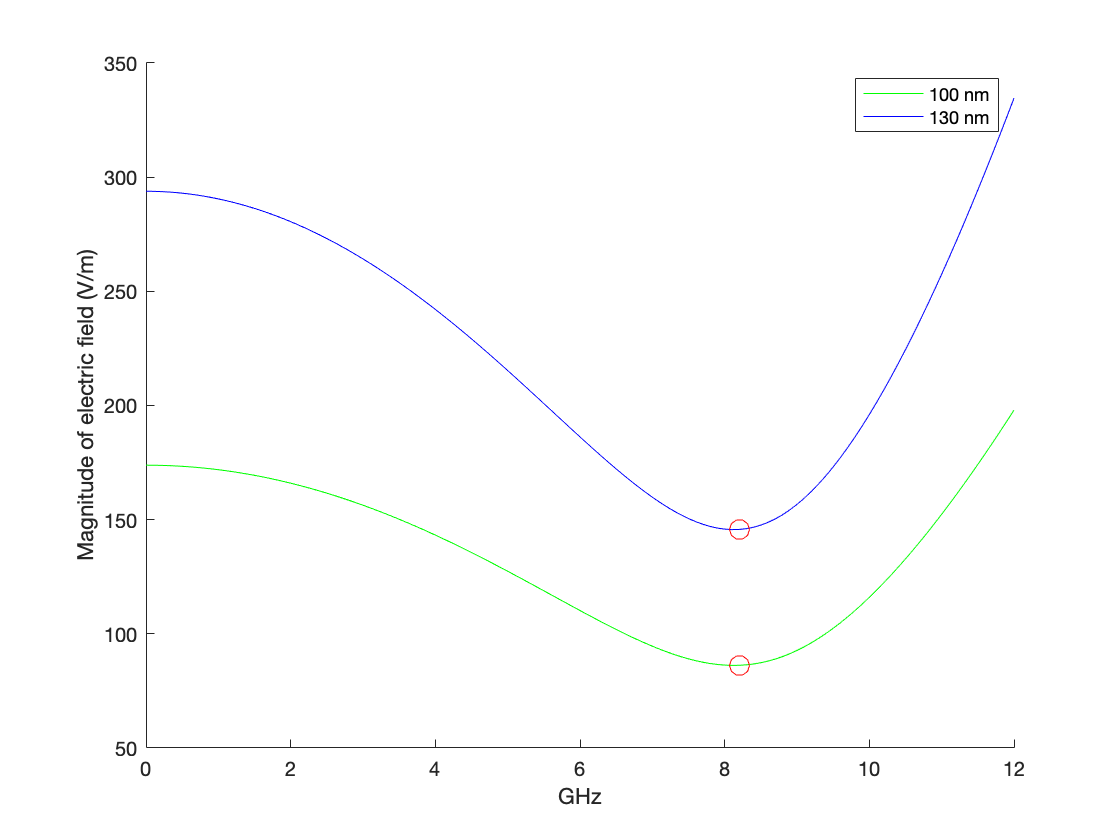

hold on;
plot(f(1+I), min_TEMF_max, 'ro', 'MarkerSize', 10);
hold off;
legend('100 nm', '130 nm')